## Explicit Taylor Methods

In this livescript, you will learn how

- To use explicit time stepping methods to solve initial value problems

Consider the differential equation


$$\frac{dx}{dt}=k x$$


which can be used to model population growth of a species with unlimited resources.

To solve, we may apply separation of variables and integrate to give 


$$x(t)=x_{0}e^{kt}$$


where $x(0)=x_{0}}$ is the initial condition.

### The Explicit Euler Method

The idea of the explicit Euler method is that we approximate the the solution using a linear line from $x_{n}$ to $x_{n+1}$, giving 


$$x_{n+1}=x_{n}+\Big(_{}\frac{dx}{dt}\Big)_{t_{n}}\Delta t$$


Since $dx/dt$ is given by definition as $kx$, we have


$$x_{n+1}=x_{n}+kx_{n}\Delta t$$


So, to march the solution forward in time all we need to is evaluate the gradient, multiply it by the timestep, and add it onto the previous value. Which is quite simple to do in MATLAB. In fact, this is true of all single step explicit methods.

For simplicity, we'll assume that the growth rate is $k=1$, and the initial population is $x(0)=10$.

To code this up, we first need to define the relevant parameters and initialise any arrays

k = 1;               %Growth rate
dt = 0.01;           %Step size
t = 0:dt:10;         %Time
x = zeros(size(t));  %Population size
x(1) = 10;           %Initial condition

Once we've done this we can then use our discretised equation to solve for the subsequent time steps. As the number of time steps is fixed, since we're marching the solution to a fixed point in time, we can use a for loop.

for i = 1:length(t)-1
    x(i+1) = x(i)+k*x(i)*dt;
end

And plotting with the exact solution, we have

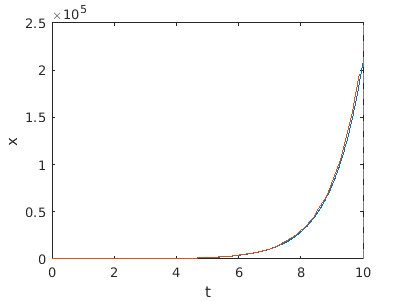

plot(t,x)
hold on
fplot(@(t) 10.*exp(t),[0,10])
hold off
xlabel('t')
ylabel('x')

Along with the error 

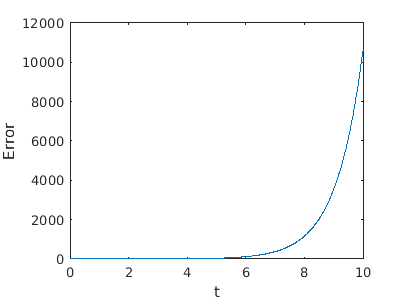

plot(t,abs(x-10.*exp(t)))
xlabel('t')
ylabel('Error')

(a)    Rerun the code with a smaller time step, see if the solution converges to the exact value.

### Second Order Taylor's Method

As we've seen previously, linear interpolation or extrapolation in this case isn't too good of an approximation. Instead, in a somewhat similar fashion to spline interpolation, we could use a higher order extrapolation method by using the second derivative at $t_{n}$ as a second degree of freedom.

This therefore gives us the iterative formula


$$x_{n+1}=x_{n}+\Delta tf(t_{n},x_{n})+\frac{\Delta t^{2}}{2}\Big(\frac{\partial f}{\partial t}+\frac{\partial f}{\partial x}f(t_{n},x_{n})\Big)$$


The only problem here is that we have to evaluate the partial derivatives of $f$ in order to solve. This can be a problem if $f$ is complicated, but there are methods of approximating the derivative terms such that the order of convergence is equivalent, which we'll cover later.

Evaluating the derivatives, we find that


$$\frac{\partial f}{\partial t} = 0\\
\frac{\partial f}{\partial x}=k$$


Hence, the second order Taylor's method becomes


$$x_{n+1}=x_{n}+\Delta t k x_{n}+\frac{\Delta t^{2}}{2}k^{2}x_{n}$$


Since only the iterative formula has changed between the two methods, all we have to do to implement the second order Taylor's method is to change the code snippet within the loop to

Which is given by

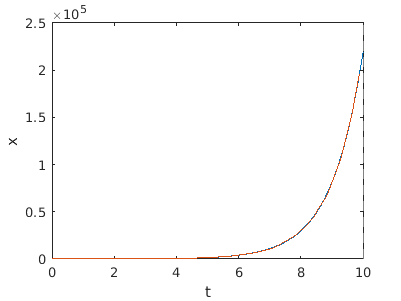

k = 1;               %Growth rate
dt = 0.01;           %Step size
t = 0:dt:10;         %Time
x = zeros(size(t));  %Population size
x(1) = 10;           %Initial condition

for n = 1:length(t)-1
    x(n+1) = x(n)+k*x(n)*dt+(dt^2/2)*k^2*x(n);
end

plot(t,x)
hold on
fplot(@(t) 10.*exp(t),[0,10])
hold off
xlabel('t')
ylabel('x')

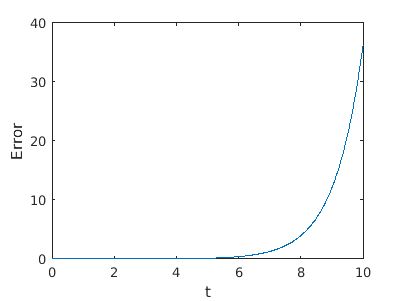


plot(t,abs(x-10.*exp(t)))
xlabel('t')
ylabel('Error')